# Print Generator for FibreForce

**Notes: **

- 1920x1080px is the size of the PNG file necessary for printing.

- The unit conversion is 3.5um per 1px 

- White pixels will be polymerized, black will not. (Structures should be white)

Code last updated 07.30.24 - Loren Phillips

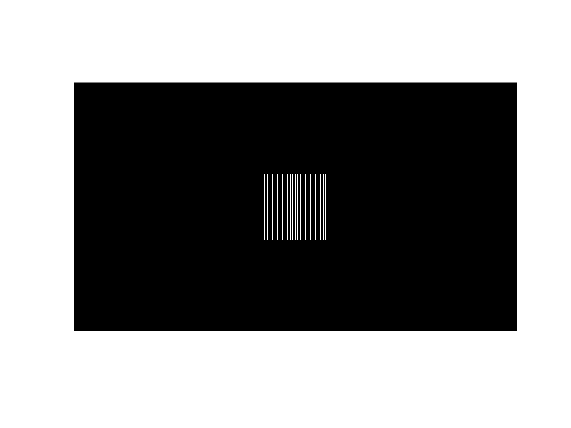

image_width = 1920; % Size of the image
image_height = 1080; % Size of the image

line_height = 285; % height of each line in pixels
line_width = 3; % width of each line in pixels
line_spacing = 3; % spacing between lines in pixels
num_lines = 50; % total number of lines

binary_matrix = zeros(image_height, image_width); % Initialize the binary matrix for the image

total_width = num_lines * line_width + (num_lines - 1) * line_spacing; % Calculate the starting position for the first line to center the array
start_x = round((image_width - total_width) / 2);
start_y = round((image_height - line_height) / 2);

for i = 0:(num_lines - 1) % Loop to set the lines in the binary matrix
    x_position = round(start_x + i * (line_width + line_spacing));
    binary_matrix(start_y:start_y+line_height-1, x_position:x_position+line_width-1) = 1;
end

imshow(binary_matrix, 'InitialMagnification', 'fit');

file_name = input('Enter the desired file name (without extension): ', 's');
file_name = strcat(file_name, '.png');

imwrite(binary_matrix, file_name); % Write image to current directory

disp(['Image saved as ', file_name]);

Image saved as Fiber_File_25.png
